# E7: Segmentació

SEGMENTACIÓ BINÀRIA

Watershed: segmentació per àrea 

- Separació de cèl·lules (Sobre marcadors o sobre mínims locals per la transformada de la distància)

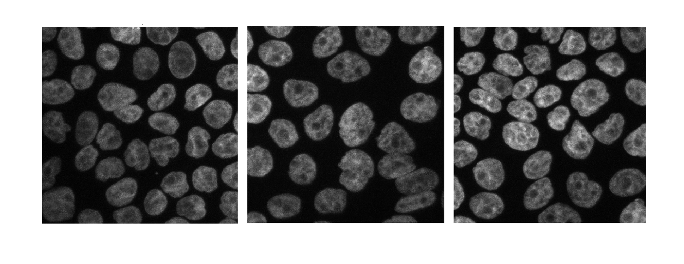

I = rgb2gray(imread("cellsegmentationcompetition.png"));
imshow(I);

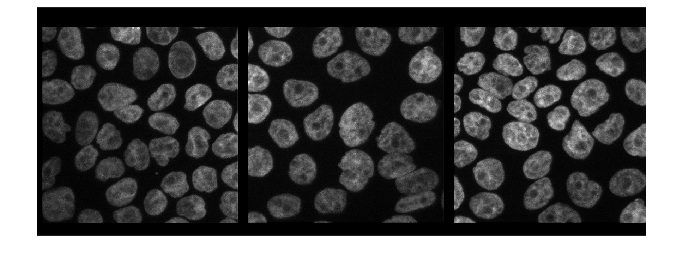

BW = I > 250;
M = false(size(I));
M(:,1) = 1;
M(:,end) = 1;
M(1,:) = 1;
M(end,:) = 1;

REC = imreconstruct(M,BW);

REC = imdilate(REC, strel("square", 5));

I = I - 255*uint8(REC);

imshow(I);

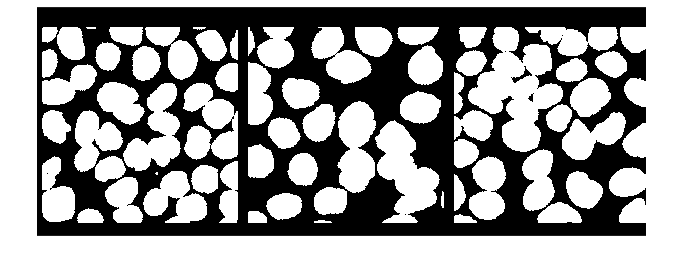


I = medfilt2(I, [3, 3]);
BW = I > 16;
BW = imopen(BW,strel("square", 3));

% cèl·lues binaritzades
imshow(BW);

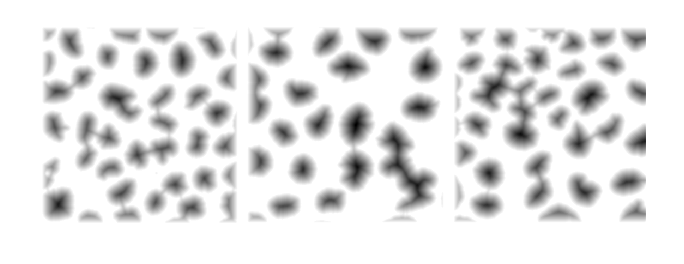


% quan de prop està cada píxel del centre de la cèl·lula
TD = -bwdist(not(BW), "quasi-euclidean");

% filtrar TD perquè té masses mínims locals
TD = medfilt2(TD, [6, 6]);

imshow(TD,[])

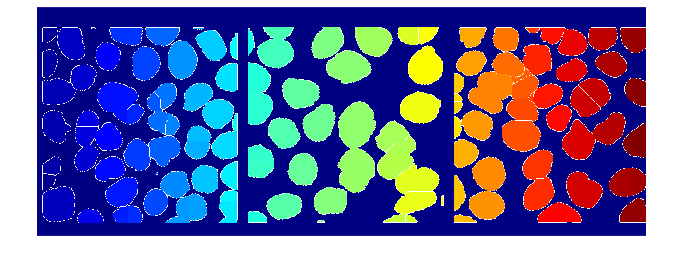

TD(not(BW)) = -Inf; % per evitar la propagació de l'aigua en el Background 

% WS -> imatges d'etiquetes de pous
WS = watershed(TD);

IB = WS == 0;

RGB = label2rgb(WS);

imshow(RGB);

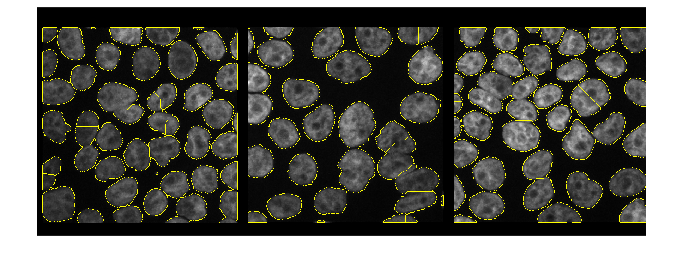


O = imoverlay(I, IB);

imshow(O);

Exercici Cornea

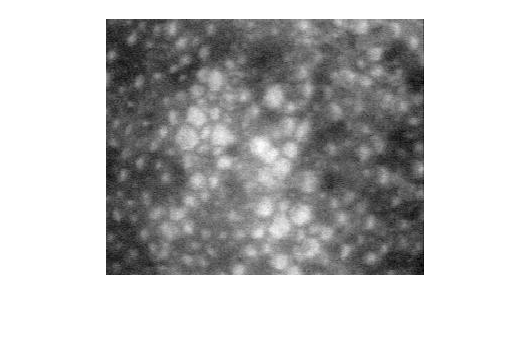

I = imread("cornea.tif");
imshow(I);

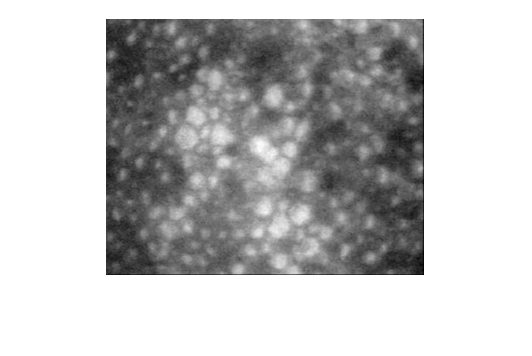


I = medfilt2(I,[2 2]); %filtrat de mediana
imshow(I);

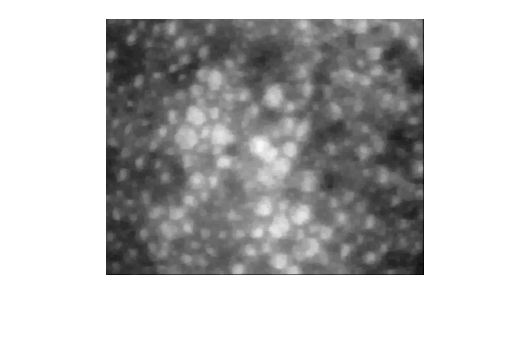


% filtrat morfològic

SE = fspecial("disk",1) > 0;
%SE = ones(5,5);
IFM = imopen(I,SE); % open
IFM = imclose(IFM,SE); % open-close

imshow(IFM);

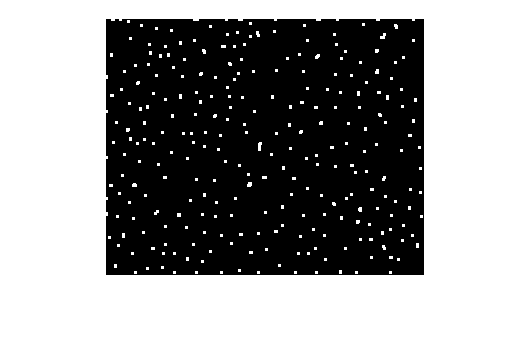



% màxims regionals

IRM = imregionalmax(IFM);

imshow(IRM);

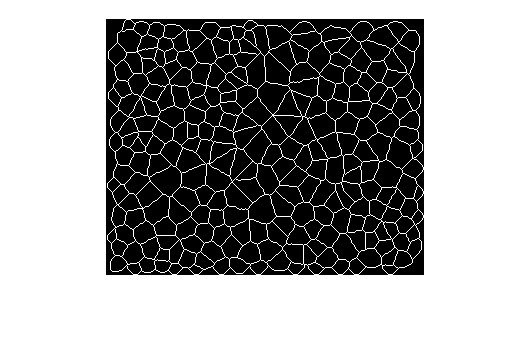


% SKIZ

SK = bwskel(not(IRM));
SKIZ = bwmorph(SK, "spur", Inf); % elimina les puntes iterativament fins que res canvia
SKIZ = SKIZ & not(bwhitmiss(SKIZ, [-1 -1 -1; -1 1 -1; -1 -1 -1])); % Hit and miss podem eliminar pixels aillats

imshow(SKIZ);

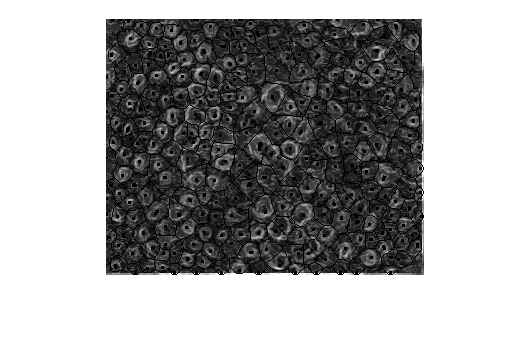


% imatge gradient
Grad = uint8(imgradient(I));

G = imimposemin(Grad, SKIZ|IRM); % Sino en la imatge gradient hi han molts minims locals 
imshow(G,[]);

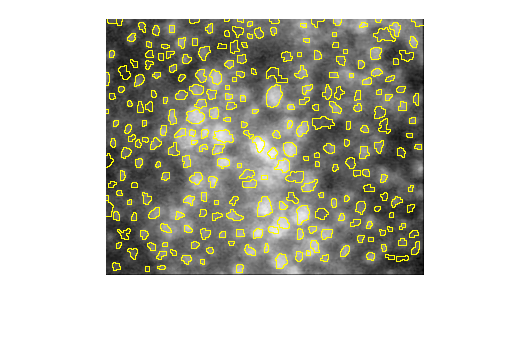


% Watershed
WS = watershed(G);
IB = WS == 0;
RGB = imoverlay(I, IB);
imshow(RGB);

SEGMENTACIÓ PER COLOR

Simplificar el nombre de colors

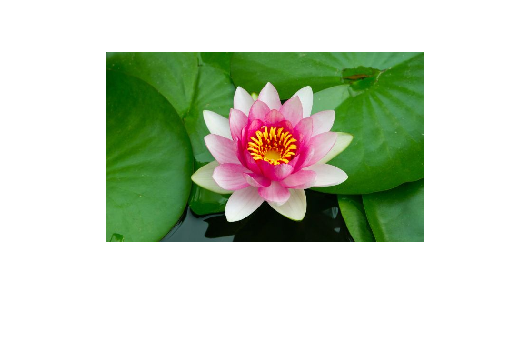

I = imread("nenufar.jpg");
imshow(I);

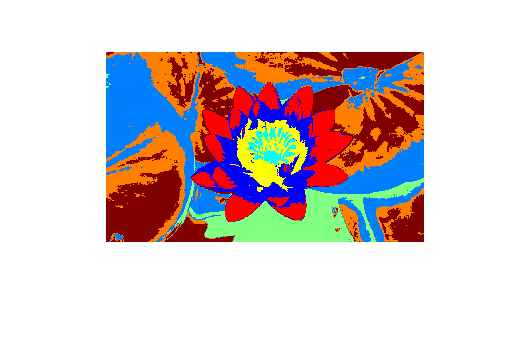

[f,c,p] = size(I);
R = I(:,:,1);
G = I(:,:,2);
B = I(:,:,3);
O = [R(:), G(:), B(:)];
[C,Centroide] = kmeans(double(O), 8);
C = reshape(C, [f, c]);
RGB = label2rgb(C);

imshow(RGB);

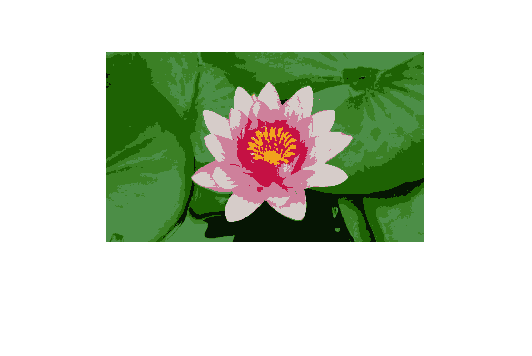


RGB2 = I;

for i = 1:f
    for j = 1:c
        rgb = Centroide(C(i,j),:);
        RGB2(i,j,1) = uint8(rgb(1));
        RGB2(i,j,2) = uint8(rgb(2));
        RGB2(i,j,3) = uint8(rgb(3));
    end
end

imshow(RGB2);